% Setting initial values
clear;clc;
TR = 100;
T2_dephasing = 50;
n=91;
TE = 5;
Alpha = linspace(0,pi/2,n);

% Find  maximum MRI image brightness
T1 = 1000;
M_initial = ((1-exp(-TR/T1)).*sin(Alpha))./(1-exp(-TR/T1).*cos(Alpha))*exp(-TE/T2_dephasing); 
Mz_angle = Alpha(find(M_initial==max(M_initial(:))))/pi*180;
fprintf('T1: %d', T1)

T1: 1000

fprintf('Angle of max(Mz): %d\n', Mz_angle)

Angle of max(Mz): 25


% Find the curve local maximum or minimum
% By differences and approximate derivatives
T1 = 1000;

syms a
f = ((1-exp(-TR/T1))*sin(a))/(1-exp(-TR/T1)*cos(a))*exp(-TE/T2_dephasing);
% Solve (find the maximum)
g = diff(f);
s = solve(g);
angle = s(2)/pi*180;
fprintf('Angle of max(Mz): %f\n\n',angle)

Angle of max(Mz): 25.198605



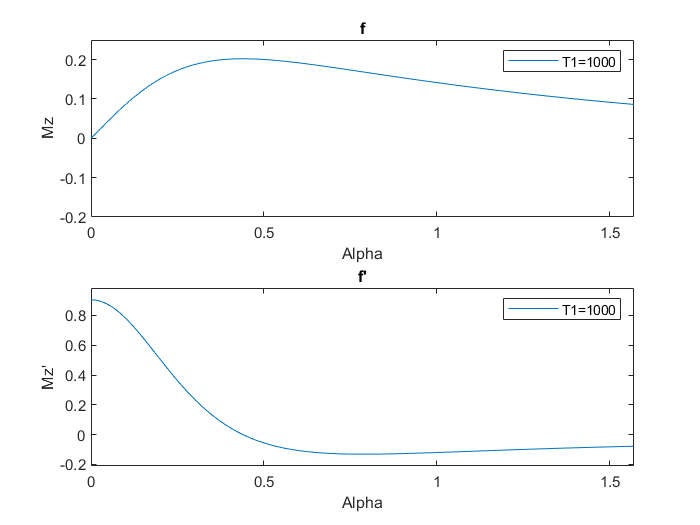


% Plot Mz
figure();
subplot(211)
ezplot(f, [0 pi/2])
title("f")
ylabel("Mz")
xlabel("Alpha")
legend("T1=1000")
axis([0 pi/2 -0.2 0.25]);
%text(s(2), subs(f, s(2)), 'local max','Color','b')
% Plot Mz'
subplot(212)
ezplot(g, [0 pi/2])
title("f'")
ylabel("Mz'")
xlabel("Alpha")
legend("T1=1000")

% Find  maximum MRI image brightness
T1 = 1100;
M_initial = ((1-exp(-TR/T1)).*sin(Alpha))./(1-exp(-TR/T1).*cos(Alpha))*exp(-TE/T2_dephasing); 
Mz_angle = Alpha(find(M_initial==max(M_initial(:))))/pi*180;
fprintf('T1: %d', T1)

T1: 1100

fprintf('Angle of max(Mz): %d\n', Mz_angle)

Angle of max(Mz): 24


% Find the curve local maximum or minimum
% By differences and approximate derivatives
T1 = 1100;

syms a
f = ((1-exp(-TR/T1))*sin(a))/(1-exp(-TR/T1)*cos(a))*exp(-TE/T2_dephasing);
% Solve (find the maximum)
g = diff(f);
s = solve(g);
angle = s(2)/pi*180;
fprintf('Angle of max(Mz): %f\n',angle)

Angle of max(Mz): 24.062573


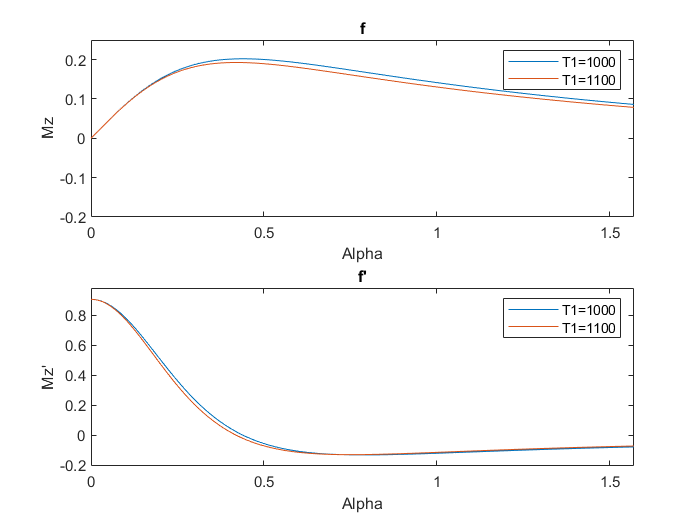


% Plot Mz
subplot(211)
hold on;
ezplot(f, [0 pi/2])
title("f")
ylabel("Mz")
xlabel("Alpha")
legend("T1=1000", "T1=1100")
%text(s(2), subs(f, s(2)), 'local max','Color','r')
axis([0 pi/2 -0.2 0.25]);
% Plot Mz'
subplot(212)
hold on;
ezplot(g, [0 pi/2])
title("f'")
ylabel("Mz'")
xlabel("Alpha")
legend("T1=1000", "T1=1100")

% Find the curve local maximum or minimum
% By differences and approximate derivatives
T1 = 1500;

syms a
f = ((1-exp(-TR/T1))*sin(a))/(1-exp(-TR/T1)*cos(a))*exp(-TE/T2_dephasing);
% Solve (find the maximum)
g = diff(f);
s = solve(g);
angle = s(2)/pi*180;
fprintf('Angle of max(Mz): %f\n',angle)

Angle of max(Mz): 20.689793


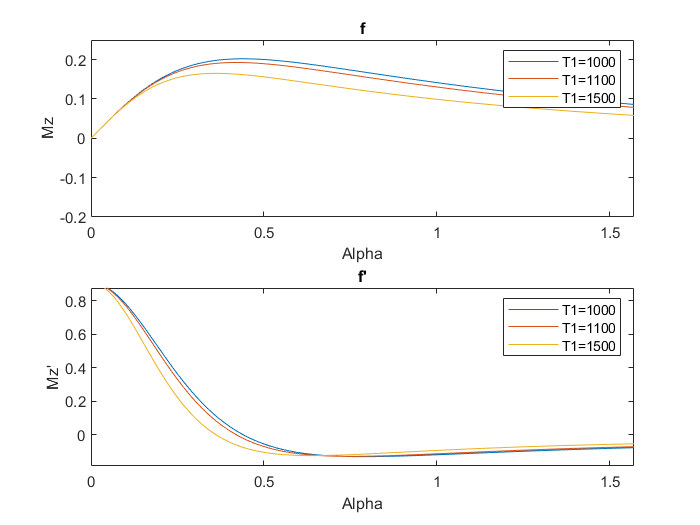


% Plot Mz
subplot(211)
hold on;
ezplot(f, [0 pi/2])
title("f")
ylabel("Mz")
xlabel("Alpha")
legend("T1=1000", "T1=1100" , "T1=1500")
axis([0 pi/2 -0.2 0.25]);
%text(s(2), subs(f, s(2)), 'local max','Color','y')
% Plot Mz'
subplot(212)
hold on;
ezplot(g, [0 pi/2])
title("f'")
ylabel("Mz'")
xlabel("Alpha")
legend("T1=1000", "T1=1100" , "T1=1500")